# Fachwerk

clear
addpath('../../../../../04-software/bofem/src')
addpath('lib')
import bofem.*;

## System

function m = makeSystem(t)
    import bofem.*;
    m = Model();
    m.addMaterial('WC24', 11000, 1, 1);
    m.addSection('R', '10x10', 0.1, 0.1);
    m.addNodes(0:2.5:10, zeros(1, 5));
    m.addNodes(0:2.5:10, -[2, 2.5, 3, 2.5, 2]);
    m.useElementType = t;
    m.useSection = 1;
    m.addElements(1:4, 2:5);
    m.addElements(6:9, 7:10);
    m.addElements(1:5, 6:10);
    m.addElements(6:7, 2:3);
    m.addElements(3:4, 9:10);
    m.setConstraint(1, [true,  true]);
    m.setConstraint(5, [false, true]);
    m.setForce([6, 10], [0, 7.5]);
    m.setForce(7:9, [0, 15]);
end

## Ergebnisse mit Fachwerkelementen

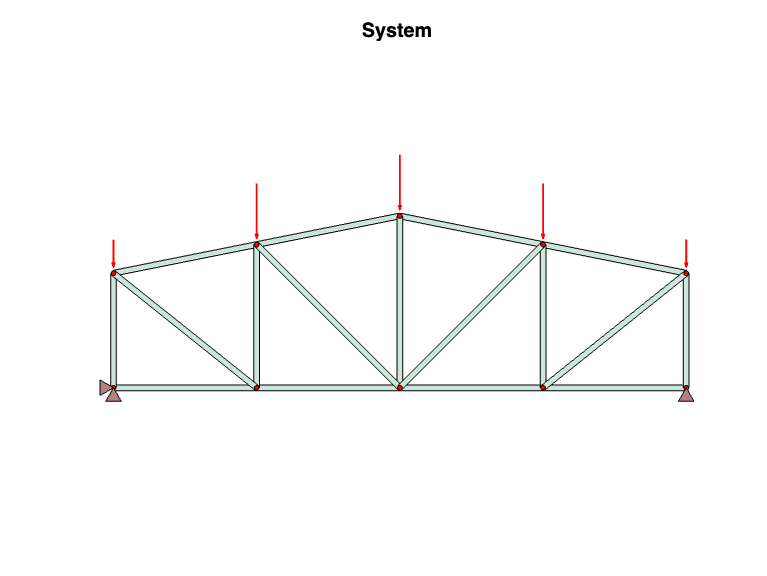

m = makeSystem('Truss2D');
m.solve();
v = Visualizer(m);
v.update()

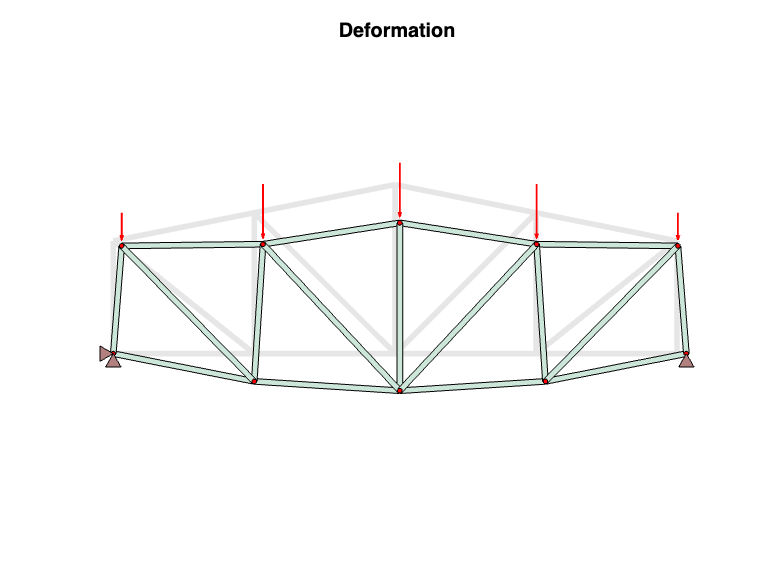

v.drawElementsDeformed = true;
v.update()

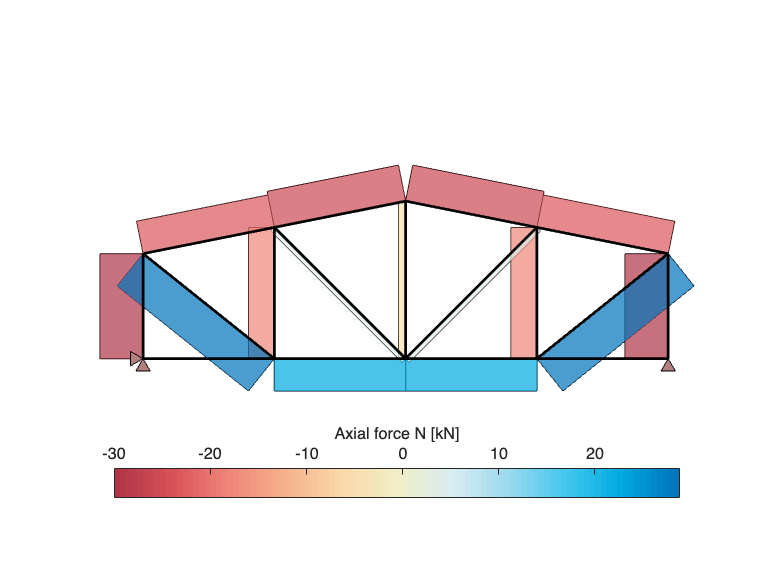

v.drawElementsDeformed = false;
v.drawElementResult = 'N';
v.update()

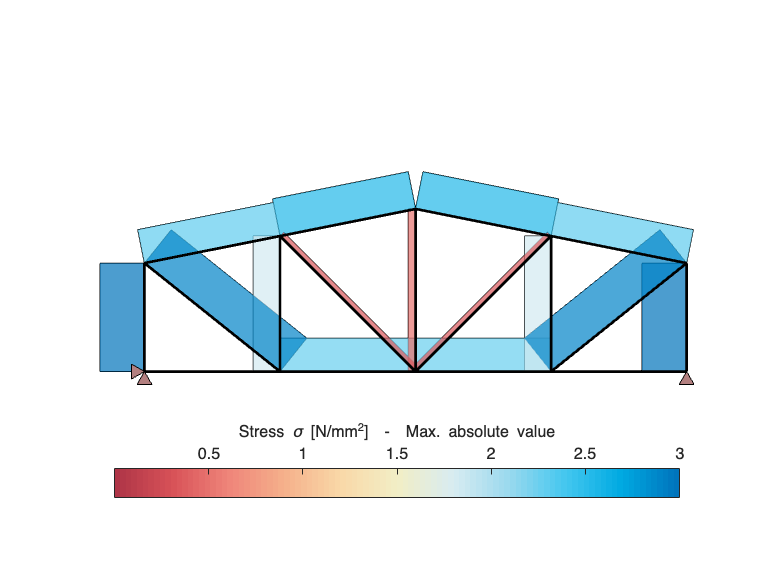

v.scaleElementResult = -1;
v.drawElementResult = 'sigma';
v.update()

Zahlenwerte

maxU = round(1000 * max(abs(m.analysisResult.solutions)), 3)

maxU = 4.2030

NMax = round(1e-3 * nMax(m))

NMax = 30

sMax = 1e-6 * sigmaMax(m)

sMax = 3.0000

## Ergebnisse mit Balkenelementen

m = makeSystem('Beam2D');
m.solve();
v = Visualizer(m);
v.update();

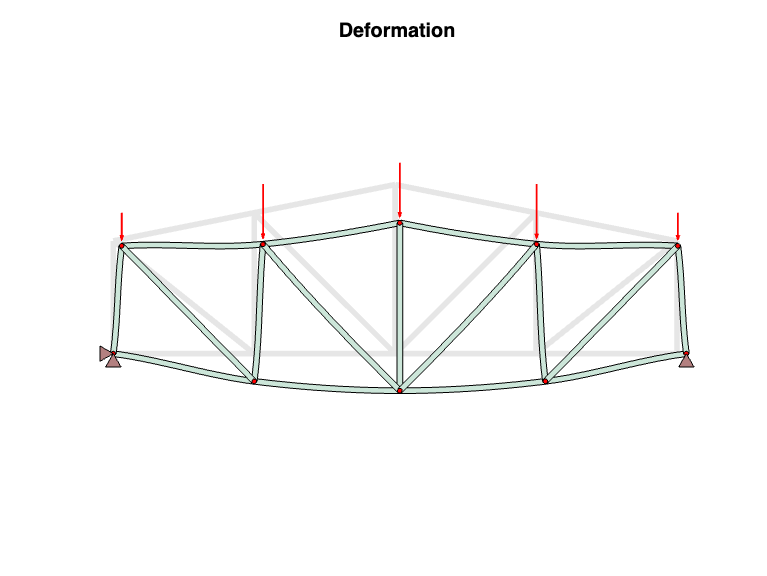

v.drawElementsDeformed = true;
v.update()

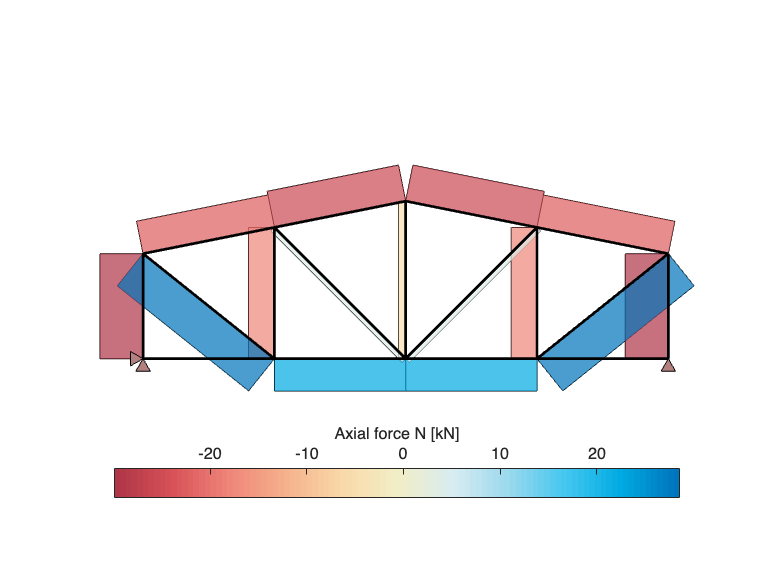

v.drawElementsDeformed = false;
v.drawElementResult = 'N';
v.update()

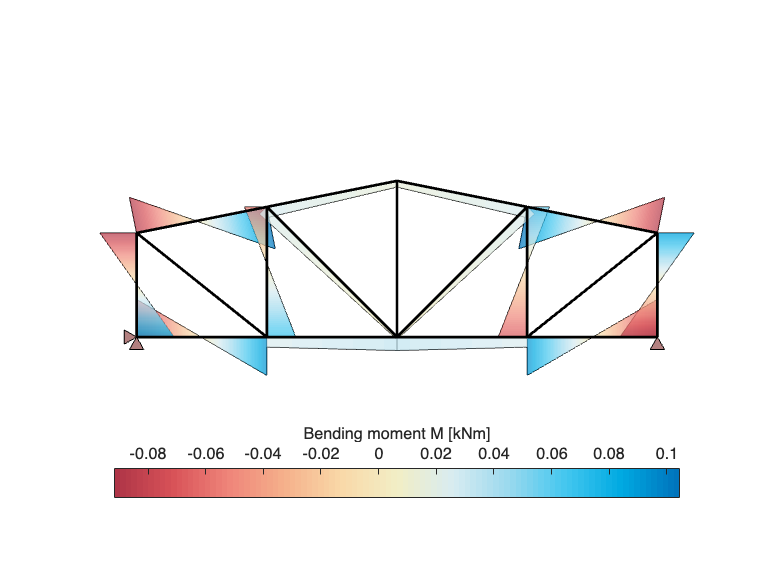

v.drawElementResult = 'M';
v.update()

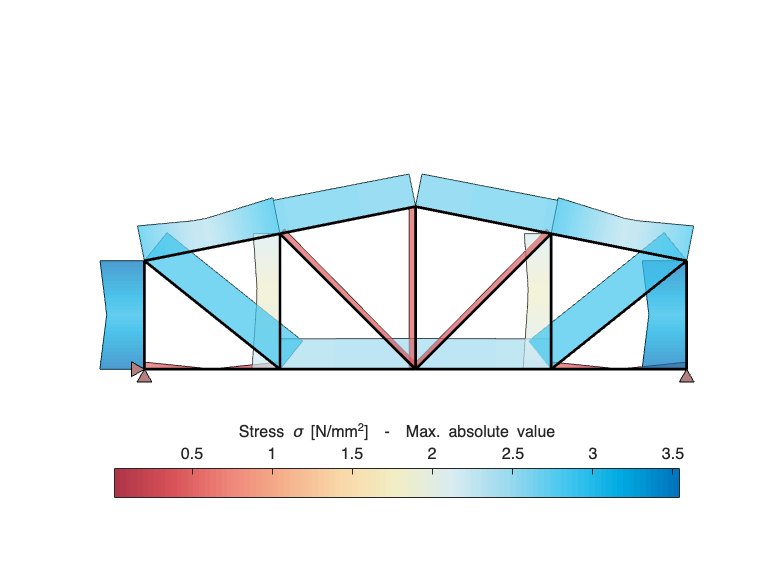

v.scaleElementResult = -1;
v.drawElementResult = 'sigma';
v.update()

Zahlenwerte

maxU = round(1000 * max(abs(m.analysisResult.solutions)), 3)

maxU = 4.1900

NMax = round(1e-3 * nMax(m), 3)

NMax = 29.9260

sMax = 1e-6 * sigmaMax(m)

sMax = 3.5428

## Kinematisches System

Auflager verschieblich

m = makeSystem('Truss2D');
v = Visualizer(m);
v.drawElementsDeformed = true;

m.setConstraint(1, [false,  true]);
m.solve();

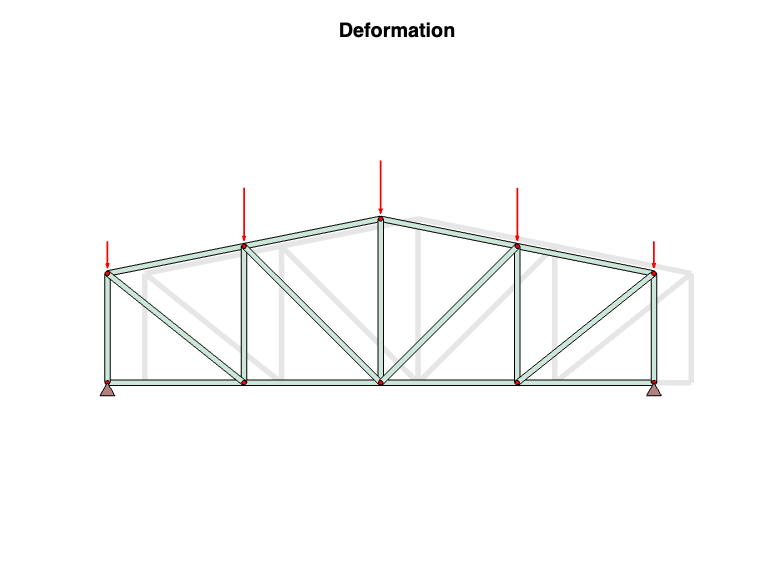


K = m.K();
[u, lambda] = eig(K);
diag(lambda)

m.setUHat(u(:, 1));
v.update()

2 Stäbe vergessen

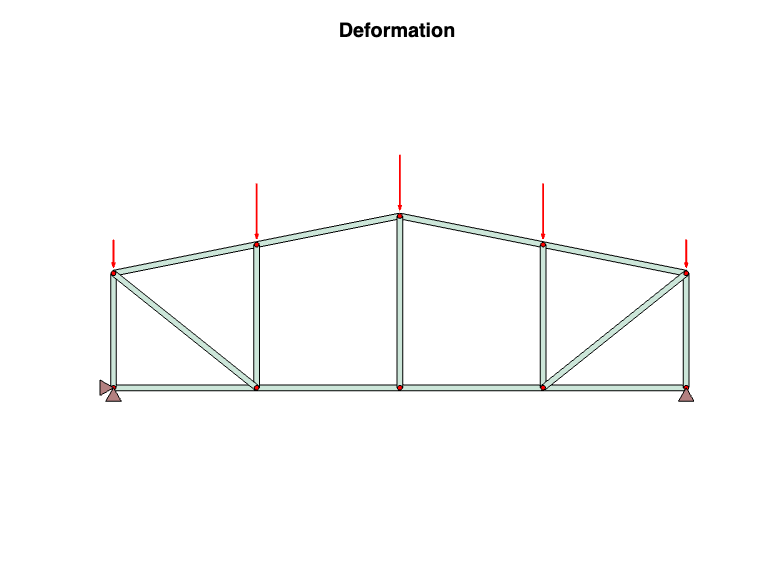

m = makeSystem('Truss2D');
v = Visualizer(m);
v.drawElementsDeformed = true;

m.removeElement(16);
m.removeElement(15);
v.update()


m.solve();

K = m.K();
[u, lambda] = eig(K);
diag(lambda(1:6, 1:6))

ans = 1.0e+07 *

   -0.0000
   -0.0000
    0.2162
    0.3750
    1.4039
    2.7676


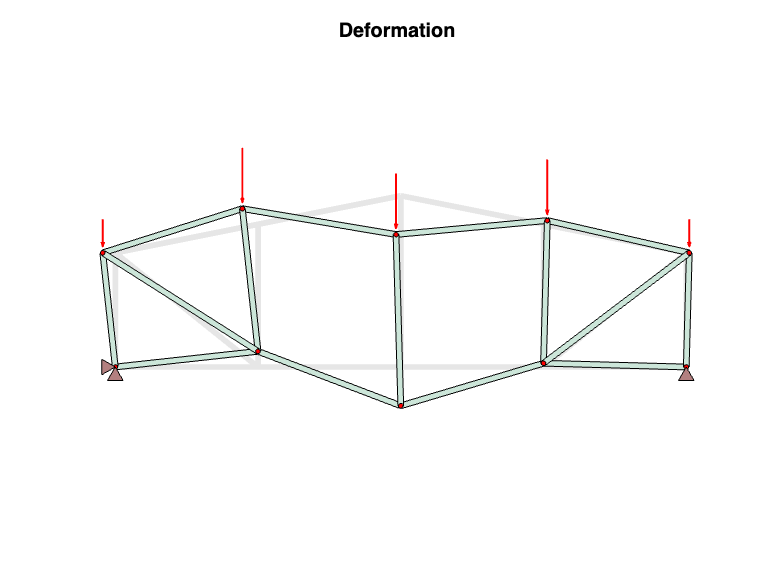


m.setUHat(u(:, 1));
v.update()

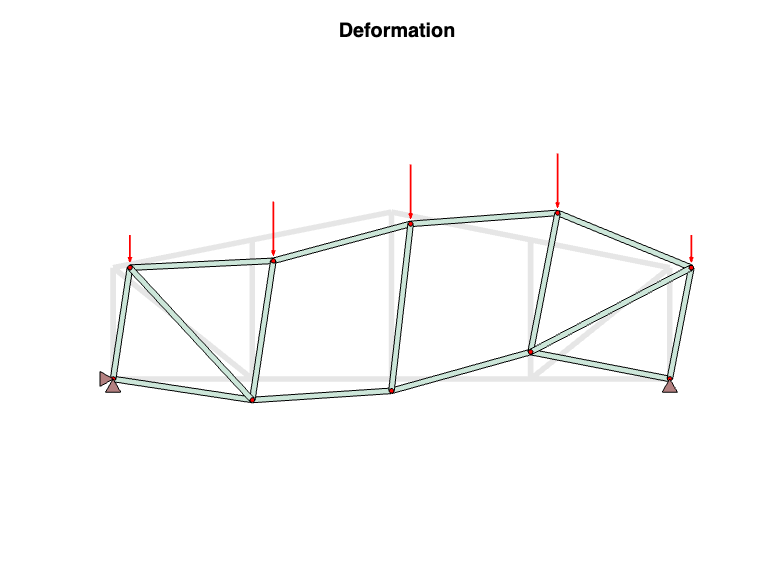

m.setUHat(u(:, 2));
v.update()